### Probabilistic Road Map Planner

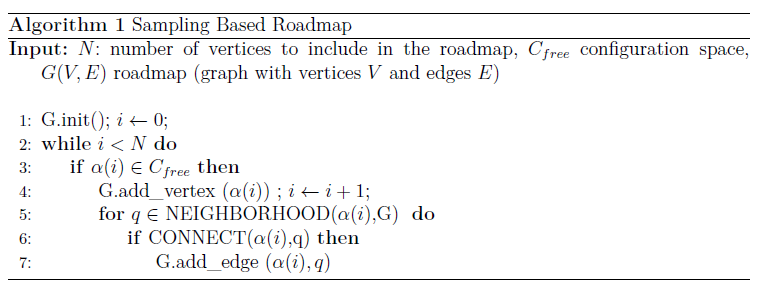

1) Load map files from ${\tt exampleMaps.mat}$ contained in maps.zip. The file contains a simple and a more complex map represented by a binary occupancy grid (logical (binary) matrix) in which an entry of $1$ indicates an occupied and $0$ an unoccupied cell in the environment. Convert the maps into binary occupancy grids, generate and visualize a probabilistic roadmap for the environment.

2) The method ${\tt binaryOccupancyMap}$ generates a 2-D occupancy grid object, which partitions the environment into free space and obstacles. The occupancy grid is constructed either from map data or sensor data in conjunction with robot pose estimates.

creates a grid from the binary entries in matrix ${\tt p}$ at a resolution ${\tt res}$ specified in cells per meter. Notice, that this differs from the definition in YAML-files which define the resolution w.r.t. meter / pixel (cell). The resolution and the dimension of the binary matrix ${\tt p} $ determine the height and width of the occupancy grid. Generate the occupancy grids from the map data with a resolution of $$2\frac{\mathrm{cells}}{\mathrm{m}}$$. Visualize both occupancy grids with ${\tt show}$.

3) Generate a probabilistic roadmap for the simple map with $50$ nodes. ${\tt mobileRobotPRM(map,numnodes)} $creates a roadmap from the binary occupancy grid ${\tt map}$, with the maximum number of nodes ${\tt numnodes}$. Visualize the road map with ${\tt show}$.

4) Generate a denser probabilistic roadmap for the larger and more complex map with $500$ nodes. Visualize the road map with ${\tt show}$.

5) Plan a collision-free path from start location $$\mathbf{x}_s=[2,1]$$ to goal location $$\mathbf{x}_g=[12,10]$$ for the simple map using ${\tt findpath}$ and visualize the roadmap and path with ${\tt show}$.

6) Plan a collision-free path from start location $$\mathbf{x}_s=[2,1]$$ to goal location $$\mathbf{x}_g=[22,18]$$  for the complex map. Visualize the roadmap and path.

7) Load the TurtleBot3 map from the image file ${\tt turtlebot3world.pgm}$ using

Generate the corresponding binary occupancy grid. Notice that a resolution of $$20$$ cells per meter corresponds to $$0.05$$ meter per pixel in PGM file. Reduce the map to the relevant area. Also consider to adapt the origin of the coordinate system in the binary occupancy grid properly. Use the property ${\tt GridLocationInWorld}$ of the ${\tt binaryOccupancyMap}$ object.

8) Start the Turtlebot3 Gazebo simulation by running the command

in a Linux terminal.

9) Plan and visualize a path that connects the robot's current location with the goal location $$\mathbf{x}_g= [0,2]$$ with the probabilistic road map planner in Matlab. For this, query from topic ${\tt odom}$ and use the helper function ${\tt OdometryMsg2Pose}$ to obtain the current robot pose.

10) Launch RViz by running the command

in a Linux terminal. 

11) Query the goal pose from the topic ${\tt /move\_base\_simple/goal}$ rather than using a fixed goal pose. Use the helper function ${\tt PoseStampedMsg2Pose}$ to convert the ROS message. Plan and visualize the path for the new custom goal location.

12) Notice that currently the planned path does not consider the dimensions of the circular robot and that some vertices of the roadmap are close to obstacles. To plan a safe and collision-free path inflate the occupancy grid by the robot radius. The function ${\tt inflate(map,radius)}$ enlarges occupied map cells by the specified radius. The status of free cells separated to an occupied cell by less than the radius changes to occupied (true). Inflate the world occupancy grid by the robot radius $$r=0.18\,\mathrm{m}$$ plus a safety margin $$d=0.12\,\mathrm{m}$$. Regenerate the roadmap for the world environment and replan the path.

### Rapidly Exploring Random Tree Planner

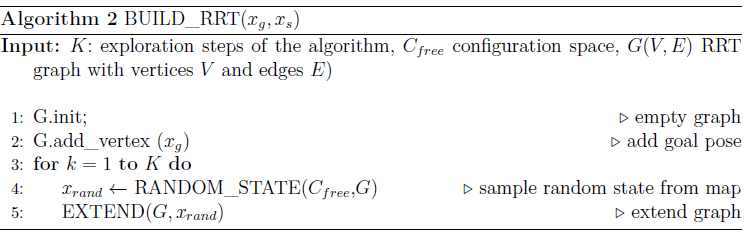

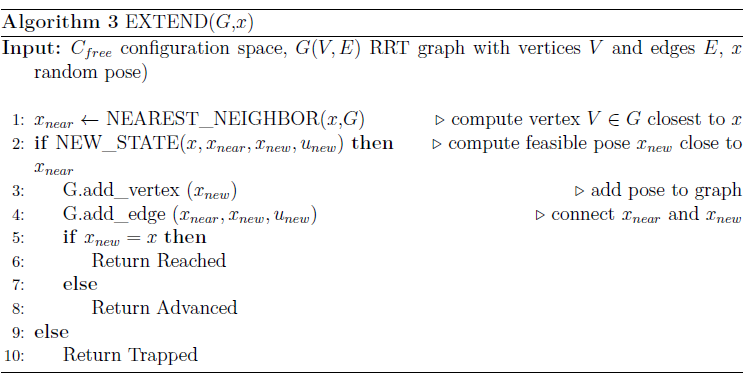

13) Plan a path for a unicycle kinematics ($\texttt{stateSpaceSE2}$) with the RRT algorithm for the complex map with start and goal pose $$x_i=[2 \; 1 \; \pi/2]$$ and $$x_f = [22 \; 18 \; \pi/2]$$. Visualize the path and the tree using the helper function ${\tt displayAndPlotPlanningResult}$.

14) Plan a path for a Dubins and Reeds-Shepp vehicle with minimum turning radius $$r_{min}=2.0$$ with the RRT algorithm for the complex map with start and goal pose $$x_i=[2 \; 1 \; \pi/2]$$ and $$x_f = [22 \; 18 \; \pi/2]$$. It is advisable to use a Drop Down control field in the Live Editor code to select the planner and the state space model from a drop down list of options.

Since the $\texttt{stateSpaceSE2}$ model does not possess the property $\texttt{MinTurningRadius}$ do the assignment only for the Dubins and ReedsShepp state space model.

15) Visualize the path and the tree. 

16) Report the number of iterations and the path length for the three kinematic models according to the table below.

resultTable = table({'RRT';'RRT';'RRT'}, {'unicycle';'Dubins';'ReedsShepp'}, zeros(3,1), zeros(3,1), 'VariableNames',{'planner', 'kinematics', '#iterations', 'path length'});
resultTable{1, '#iterations'} = 0 ;% RRT + unicylce
resultTable{1, 'path length'} = 0 ;% RRT + unicylce
resultTable{2, '#iterations'} = 0 ;% RRT + Dubins
resultTable{2, 'path length'} = 0 ;% RRT + Dubins
resultTable{3, '#iterations'} = 0 ;% RRT + Reeds-Shepp
resultTable{3, 'path length'} = 0 ;% RRT + Reeds-Shepp
disp(resultTable);

17) Investigate the effect of the planner property $\texttt{MaxConnectionDistance}$ on the number of iterations as well as the path length. It is advisable to use a Numeric Slider control field in the Live Editor to easily explore different values for $\texttt{MaxConnectionDistance}$.

### Bidirectional Rapidly Exploring Random Trees

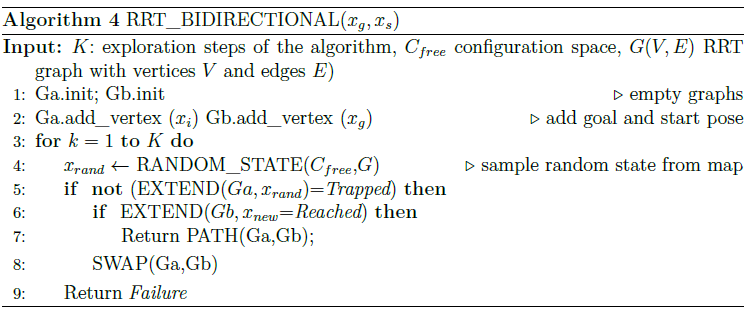

18) Plan a path for a unicycle kinematics ($\texttt{stateSpaceSE2}$) with the BiRRT algorithm for the complex map with start and goal pose $$x_i=[2\; 1\; \pi/2]$$ and $$x_f = [22\; 18\; \pi/2]$$.

19) Visualize the path and the two trees. For this, extend the helper function ${\tt displayAndPlotPlanningResult}$ accordingly.

20) Plan a path for a Dubins and Reeds-Shepp vehicle ($$r_{min}=2.0$$) with the BiRRT algorithm for the complex map with start and goal pose $$x_i=[2\; 1\; \pi/2]$$ and $$x_f = [22\; 18\; \pi/2]$$.

21) Report the number of iterations and the path length for the three kinematic models in the table below.

resultTable = table({'RRT';'RRT';'RRT';'BiRRT';'BiRRT';'BiRRT'}, {'unicycle';'Dubins';'ReedsShepp';'unicycle';'Dubins';'ReedsShepp'}, zeros(6,1), zeros(6,1), 'VariableNames',{'planner', 'kinematics', '#iterations', 'path length'});
resultTable{1, '#iterations'} = 0 ;% RRT + unicylce
resultTable{1, 'path length'} = 0 ;% RRT + unicylce
resultTable{2, '#iterations'} = 0 ;% RRT + Dubins
resultTable{2, 'path length'} = 0 ;% RRT + Dubins
resultTable{3, '#iterations'} = 0 ;% RRT + Reeds-Shepp
resultTable{3, 'path length'} = 0 ;% RRT + Reeds-Shepp
resultTable{4, '#iterations'} = 0 ;% BiRRT + unicylce
resultTable{4, 'path length'} = 0 ;% BiRRT + unicylce
resultTable{5, '#iterations'} = 0 ;% BiRRT + Dubins
resultTable{5, 'path length'} = 0 ;% BiRRT + Dubins
resultTable{6, '#iterations'} = 0 ;% BiRRT + Reeds-Shepp
resultTable{6, 'path length'} = 0 ;% BiRRT + Reeds-Shepp
disp(resultTable);

22) Investigate the effect of the flag $\texttt{EnableConnectHeuristic}$ on the number of iterations as well as the path length.

23) (Optional) Investigate the performance of ther RRT* planning algorithm (${\tt plannerRRTStar}$).

# Helper Functions

function [ x, y, theta ] = OdometryMsg2Pose( odomMsg )
    % convert odometry message to vector
    x=odomMsg.Pose.Pose.Position.X;
    y=odomMsg.Pose.Pose.Position.Y;
    eul=quat2eul([odomMsg.Pose.Pose.Orientation.W odomMsg.Pose.Pose.Orientation.X  odomMsg.Pose.Pose.Orientation.Y odomMsg.Pose.Pose.Orientation.Z]);
    theta=eul(1);
end

function [ x, y, theta ] = PoseStampedMsg2Pose( poseMsg )
    % convert odometry message to vector
    x=poseMsg.Pose.Position.X;
    y=poseMsg.Pose.Position.Y;
    eul=quat2eul([poseMsg.Pose.Orientation.W poseMsg.Pose.Orientation.X  poseMsg.Pose.Orientation.Y poseMsg.Pose.Orientation.Z]);
    theta=eul(1);
end

function displayAndPlotPlanningResult(pathObj, solnInfo, map)
    if ~solnInfo.IsPathFound
        disp('no path found');
    else
        disp(['number of iterations=' num2str(solnInfo.NumIterations)]);
        disp(['total pathlength=' num2str(pathObj.pathLength(),2)]);
        
        % show map
        show(map);
        hold on
        
        % plot tree data
        plot(solnInfo.TreeData(:,1),solnInfo.TreeData(:,2),'.-'); % tree expansion
        
        % plot states
        plot(pathObj.States(:,1),pathObj.States(:,2),'r-','LineWidth',2); % draw path
                
        hold off;
    end
end